# Solve System of Linear Equations

Declare the system of equation simplified

## In first approach we consider t = 1 and amplitude = 1

Supposition: t=1 ce qui implique: t = t^2 = t^3 = t^4...

% Time in second
t = 0.5

t = 0.5000

% Distance in meters
y_scaling_m = 1

y_scaling_m = 1

syms a3 a4 a5
eqn1 = a3   + a4    + a5    == 1;
eqn2 = 3*a3 + 4*a4  + 5*a5  == 0;
eqn3 = 6*a3 + 12*a4 + 20*a5 == 0;


Use equationsToMatrix to convert the equations into the form AX = B. The second input to equationsToMatrix specifies the independent variables in the equations.


[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [a3, a4, a5])

$$A = \left(\begin{array}{ccc} 1 & 1 & 1\\ 3 & 4 & 5\\ 6 & 12 & 20 \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

Use linsolve to solve AX = B for the vector of unknowns X.


an = linsolve(A,B)

$$an = \left(\begin{array}{c} 10\\ -15\\ 6 \end{array}\right)$$

On peut noter que si la valeur finale change d'un facteur d'amplitude fAmp, les valeur de a3, a4 et a5 changent selon le même facteur.

# Tentative en introduisant time & amplitude variable


syms a3 a4 a5
eqn1 = a3*t^3   + a4*t^4    + a5*t^5    == y_scaling_m;
eqn2 = 3*a3*t^2 + 4*a4*t^3  + 5*a5*t^4  == 0;
eqn3 = 6*a3*t   + 12*a4*t^2 + 20*a5*t^3 == 0;


Use equationsToMatrix to convert the equations into the form AX = B. The second input to equationsToMatrix specifies the independent variables in the equations.

[A,B] = equationsToMatrix([eqn1, eqn2, eqn3], [a3, a4, a5])

$$A = \left(\begin{array}{ccc} \frac{1}{8} & \frac{1}{16} & \frac{1}{32}\\ \frac{3}{4} & \frac{1}{2} & \frac{5}{16}\\ 3 & 3 & \frac{5}{2} \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

Use linsolve to solve AX = B for the vector of unknowns X.

an = linsolve(A,B)

$$an = \left(\begin{array}{c} 80\\ -240\\ 192 \end{array}\right)$$

Then we should use

an(1) for a3, an(2) for a4 and an(3) for a5

We convert them as

p3 = an(1)

$$p3 = 80$$

p4 = an(2)

$$p4 = -240$$

p5 = an(3)

$$p5 = 192$$

# Plot the 3 4 5 polynomial

## Init

close all

P5_position        = [0 0 0 10 -15 6];

P5_velocity        = [0 0 30 -60 30 0];

P5_acceleration = [0 60 -180 120 0 0];

P5_jerk               = [60 -360 360 0 0 0];

P5_position =     [0 0 0 p3 p4 p5];
P5_velocity =     [0 0 3*p3 4*p4 5*p5 0];
P5_acceleration = [0 6*p3 12*p4 20*p5 0 0];
P5_jerk =         [6*p3 24*p4 60*p5 0 0 0];

|polynomial |t^0   |t^1   |t^2   |t^3   |t^4    |t^5 |  

|---------------|------|------|------|-----|-------|----|

|position          |0	|0	|0	|10	|-15  |6  |

|velocity          |0	|0	|30	|-60	|30  |0  |

|acceleration  |0	|60	|-180 |120 |0     |0  |

|jerk               |60	|-360 |360 |0	|0  |0  |

## Code avec taskCycleTime as a parameter

taskCycleTime_ms = 2;
% Use CEILING	ANY_NUM --> Return the next highest whole number. in PLC
NumberOfPoints = ceil(t*1000/taskCycleTime_ms)

NumberOfPoints = 250

### Some vectors to store results

% Define Matrix fo size 1 ; NumberOfPoints + 1
position_yAxis     = [1;NumberOfPoints+1];
velocity_yAxis     = [1;NumberOfPoints+1];
acceleration_yAxis = [1;NumberOfPoints+1];
jerk_yAxis         = [1;NumberOfPoints+1];

## T_axis with increment of 2 ms

t_xAxis = 0:taskCycleTime_ms/1000:t;

## Compute motion profile of *position*

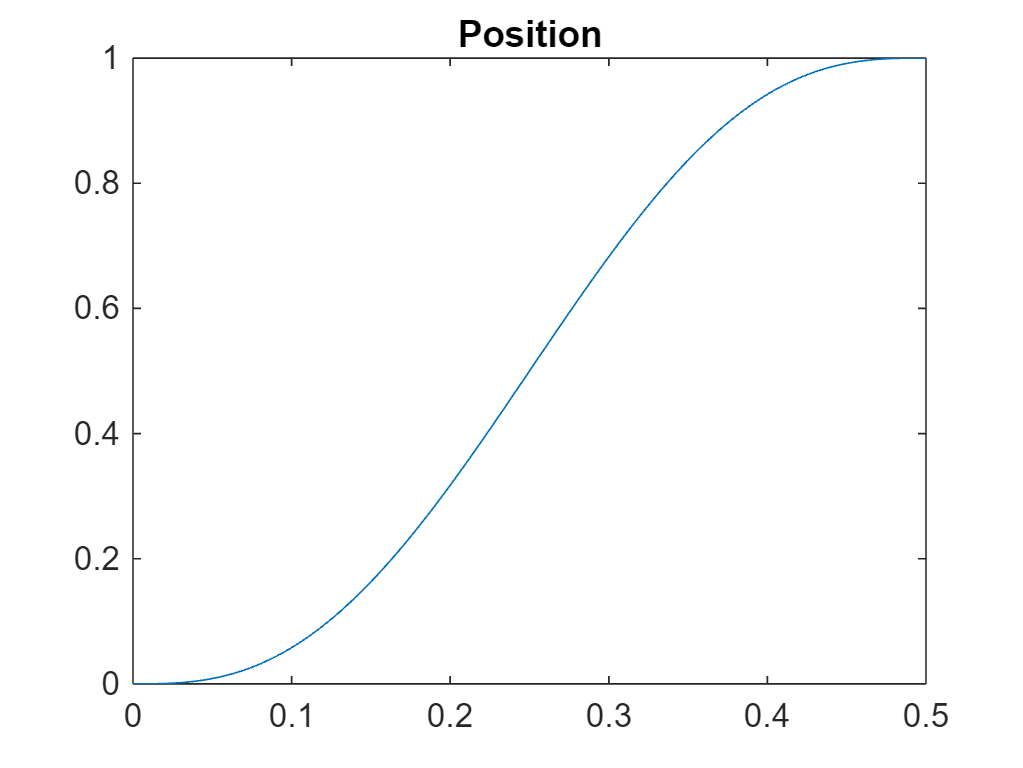

for iLoop = 1 : (NumberOfPoints + 1 )
    position_yAxis(iLoop) = (t_xAxis(iLoop)^3 * P5_position(4) + t_xAxis(iLoop)^4 * P5_position(5) + t_xAxis(iLoop)^5 * P5_position(6));
end
figure
plot(t_xAxis,position_yAxis);
title('Position')

## Compute motion profile of *velocity (m/s)*

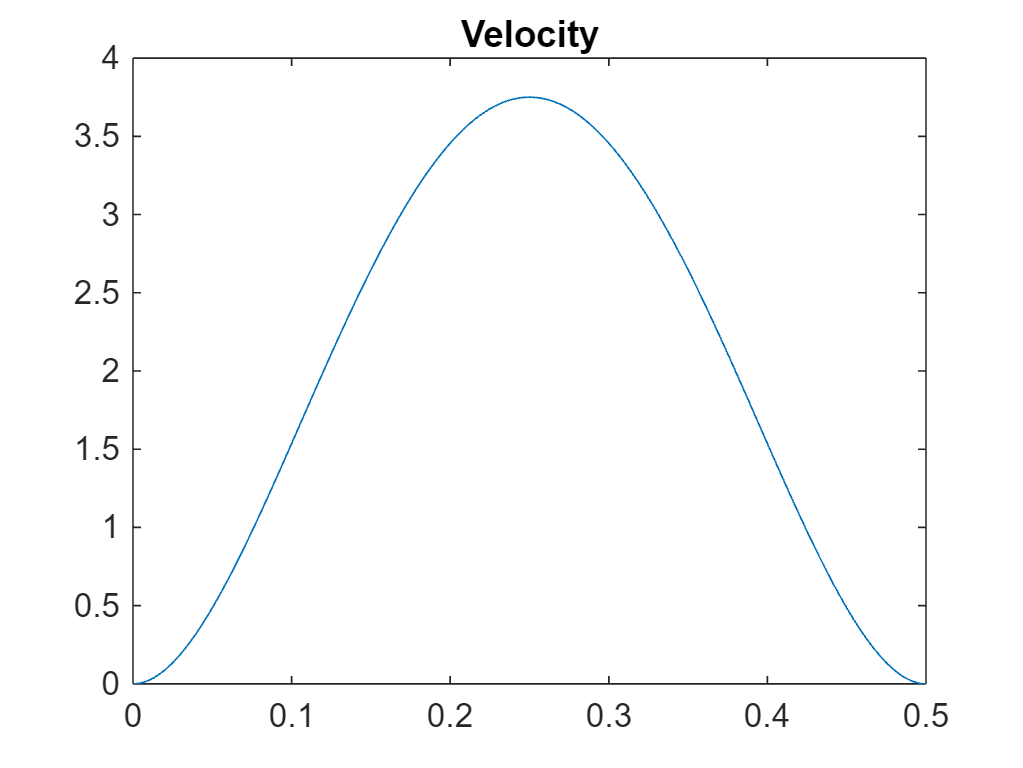

for iLoop = 1 : (NumberOfPoints + 1 )
    velocity_yAxis(iLoop) = t_xAxis(iLoop)^2 * P5_velocity(3) + t_xAxis(iLoop)^3 * P5_velocity(4) + t_xAxis(iLoop)^4 * P5_velocity(5);
end
figure
plot(t_xAxis,velocity_yAxis);
title('Velocity');


fprintf('Max velocity is %f [m/s]\n', max(velocity_yAxis));

Max velocity is 3.750000 [m/s]


## Compute motion profile of *acceleration force / torque  (m/s^2)*

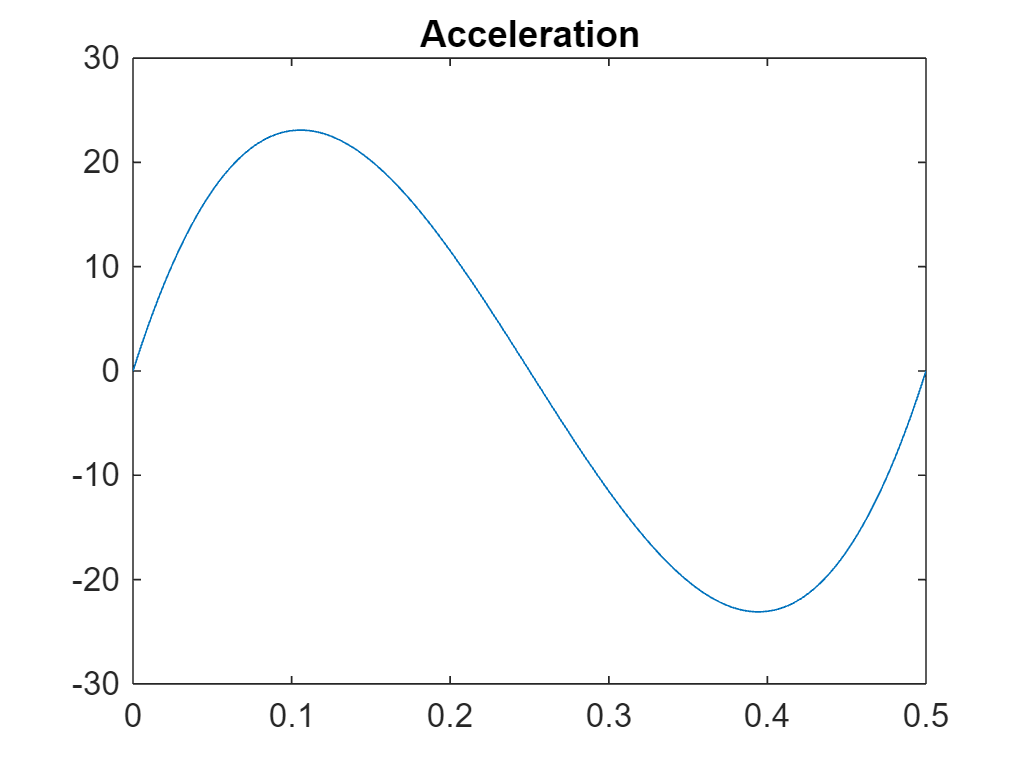

for iLoop = 1 : (NumberOfPoints + 1 )
    acceleration_yAxis(iLoop) = t_xAxis(iLoop)^1 * P5_acceleration(2) + t_xAxis(iLoop)^2 * P5_acceleration(3) + t_xAxis(iLoop)^3 * P5_acceleration(4);
end
figure
plot(t_xAxis,acceleration_yAxis);
title('Acceleration')


fprintf('Max acceleration is %f [m/s^2]\n', max(acceleration_yAxis));

Max acceleration is 23.093821 [m/s^2]


fprintf('Max deceleration is %f [m/s^2]\n', min(acceleration_yAxis));

Max deceleration is -23.093821 [m/s^2]


## Compute motion profile of *jerk  (m/s^3)*

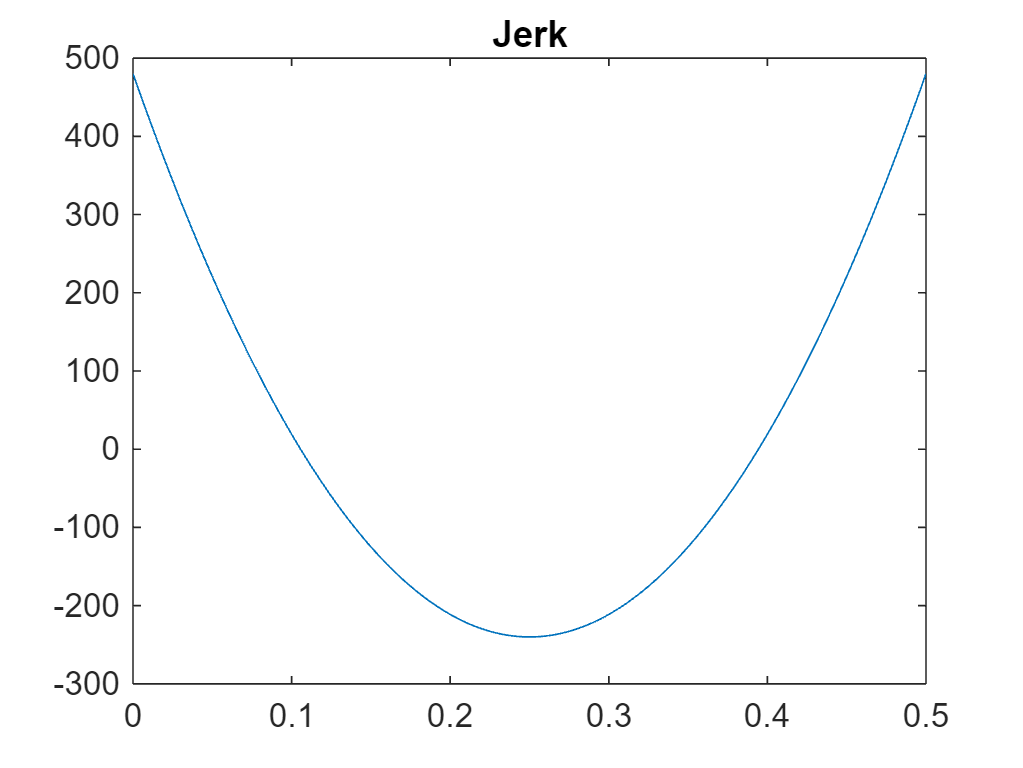

% Define Matrix fo size 1 ; NumberOfPoints + 1
jerk_yAxis = [1;(NumberOfPoints+1)];

for iLoop = 1 : (NumberOfPoints + 1 )
    jerk_yAxis(iLoop) = t_xAxis(iLoop)^0 * P5_jerk(1) + t_xAxis(iLoop)^1 * P5_jerk(2) + t_xAxis(iLoop)^2 * P5_jerk(3);
end
figure
plot(t_xAxis,jerk_yAxis);
title('Jerk')


fprintf('Max jerk is %f [m/s^3]\n', max(jerk_yAxis));

### Calcul de T1(amax) et T2(dmax)

Les extremums sont les points oû la courble du Jerk passe par 0, soit à trouver les deux points pour lesquels la courbe de Jerk, 60 - 360 t + 360 t^2 passe par 0.

En classique: at^2 + bt + c

a = 360

a = 360

b = -360

b = -360

c = 60

c = 60

t1 = (-b + sqrt(b^2-4*a*c)) / (2*a)

t1 = 0.7887

t2 = (-b - sqrt(b^2-4*a*c)) / (2*a)

t2 = 0.2113

avec la courbe d'accélération / décélération

amax = 60 * t1 -180 * t1^2 +120 * t1^3 

amax = -5.7735

dmax = 60 * t2 -180 * t2^2 +120 * t2^3 

dmax = 5.7735

End

## Même chose mais avec Temps et amplitude variable.

# Mix des deux 